c) Using your results from part (b), compute, compare, and comment on the performance of the origin-constrained and destination-constrained gravity models on UTLA-UTLA demand data (6 marks)

EQUATIONS FOR GRAVITY MODEL AND CONSTRAINED GRAVITY MODEL


$$$T_{ij} = \frac{cO_i D_j}{d^\alpha} $
$$


Origin-Constrained Equation


$$$T_{ij} = A_i \frac{D_j}{d_{ij}^\alpha} $ where $A_i = \frac{O_i}{\sum_j\frac{D_j}{d_{ij}^\alpha}}$$


Destination-Constrained Equation


$$$T_{ij} = B_j \frac{O_i}{d_{ij}^\alpha} $ where $B_j = \frac{D_j}{\sum_j\frac{O_i}{d_{ij}^\alpha}}$$


C: 0.000045
Alpha: 1.619115


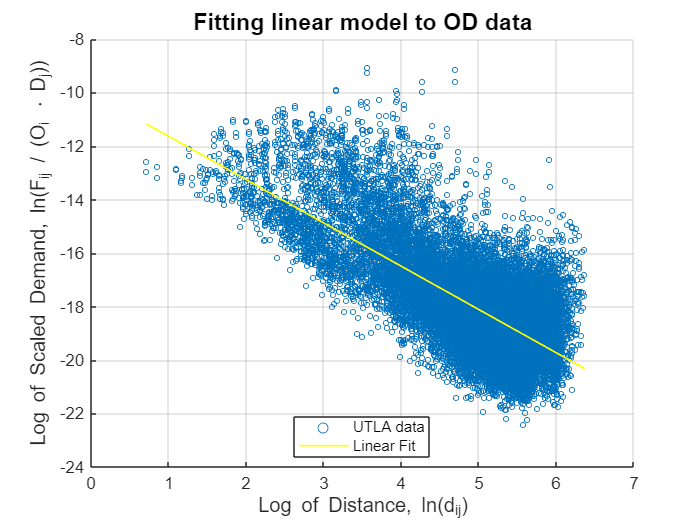

UTLAdata.odMatrix = sparse(UTLAdata.odMatrix);
UTLAdata.destinationSums = UTLAdata.destinationSums';
[c, alpha] = linearfit(UTLAdata);

% Creating gravity model
originSums = UTLAdata.originSums(:); % Ensure column vector
destinationSums = UTLAdata.destinationSums(:)'; % Ensure row vector
numerator = originSums * destinationSums * c; % Outer product
denominator = UTLAdata.distanceMatrix .^ alpha; % Element-wise power
UTLAdata.gravityU = numerator ./ denominator; % Element-wise division

diagMask = eye(size(UTLAdata.distanceMatrix)) > 0;
% Copy the distance matrix and replace diagonal elements with NaN
distanceMatrixNoDiag = UTLAdata.distanceMatrix;
distanceMatrixNoDiag(diagMask) = NaN;

% Creating origin-constrained gravity model
% Step 1: Calculate the denominator sum for each origin
% denominatorSum is a column vector of sums for each origin
denominatorSum = nansum(destinationSums ./ (distanceMatrixNoDiag .^ alpha), 2);
% Step 2: Calculate the normalization factor (A_i)
% originSums is a column vector, element-wise division ensures A_i is calculated per origin
A = originSums ./ denominatorSum;
% Step 3: Create the origin-constrained gravity model
% Recreate gravity model with normalization applied
% A is a column vector, destinationSums is a row vector, so implicit broadcasting works
UTLAdata.gravityO = (A .* destinationSums) ./ (UTLAdata.distanceMatrix .^ alpha);

% Step 1: Calculate the denominator sum for each destination
% denominatorSum is a row vector of sums for each destination
denominatorSum = nansum(originSums ./ (distanceMatrixNoDiag .^ alpha), 1);

% Step 2: Calculate the normalization factor (B_j)
% destinationSums is a row vector, element-wise division ensures B_j is calculated per destination
B = destinationSums ./ denominatorSum;

% Step 3: Create the destination-constrained gravity model
% B is a row vector, originSums is a column vector, so implicit broadcasting works
UTLAdata.gravityD = (originSums .* B) ./ (UTLAdata.distanceMatrix .^ alpha);

Verifying constrained models

UTLAdata.gravityO(logical(eye(size(UTLAdata.gravityO)))) = 0;
UTLAdata.gravityD(logical(eye(size(UTLAdata.gravityD)))) = 0;
gravityOoriginsums= sum(UTLAdata.gravityO,2)

gravityOoriginsums = 1.0e+05 *

    0.1081
    0.1828
    0.1838
    0.2369
    0.1195
    0.1777
    0.2213
    0.1627
    0.1349
    0.2544


gravityOdestinationsums = sum(UTLAdata.gravityO)

gravityOdestinationsums = 1.0e+05 *

    0.0523    0.2590    0.0666    0.2487    0.0947    0.1858    0.4124    0.2534    0.0899    0.1994    0.1846    0.0402    0.0895    0.1215    0.3119    0.6493    0.0384    0.6107    0.0522    0.1350    0.2750    0.1455    0.4595    0.1050    0.3452    0.0466    0.0300    0.0749    0.1168    0.1759    0.0892    0.1664    0.1293    0.1016    0.1449    0.1687    0.2069    0.1903    0.1460    0.1978    0.1027    0.1603    0.1867    0.0068    0.1628    0.3129    0.3078    0.1459    0.0142    0.0001


gravityDoriginsums = sum(UTLAdata.gravityD,2)

gravityDoriginsums = 1.0e+05 *

    0.0791
    0.1894
    0.1198
    0.2291
    0.0751
    0.2079
    0.2405
    0.1717
    0.0704
    0.1691


gravityDdestinationsums = sum(UTLAdata.gravityD)

gravityDdestinationsums = 1.0e+05 *

    0.0679    0.2365    0.1034    0.2561    0.1430    0.1575    0.3542    0.2158    0.1578    0.2670    0.2926    0.0873    0.1457    0.1797    0.3243    0.4479    0.0599    0.5430    0.0964    0.1716    0.3240    0.1899    0.4861    0.1423    0.3719    0.1702    0.0802    0.1296    0.2243    0.1903    0.1373    0.2039    0.1785    0.1209    0.2245    0.2086    0.2188    0.2062    0.1655    0.2807    0.2090    0.2578    0.2403    0.0124    0.2751    0.3771    0.3737    0.2437    0.0809    0.0012


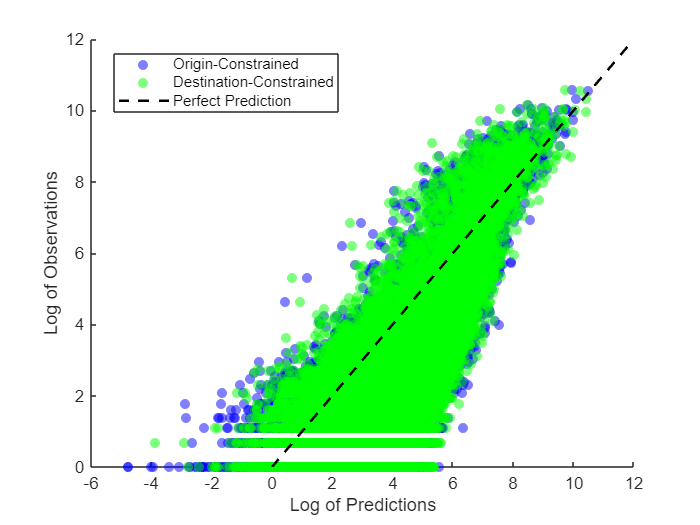

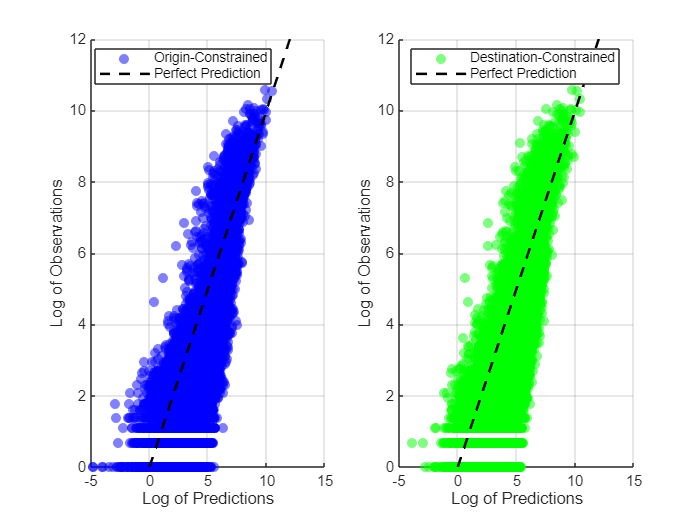

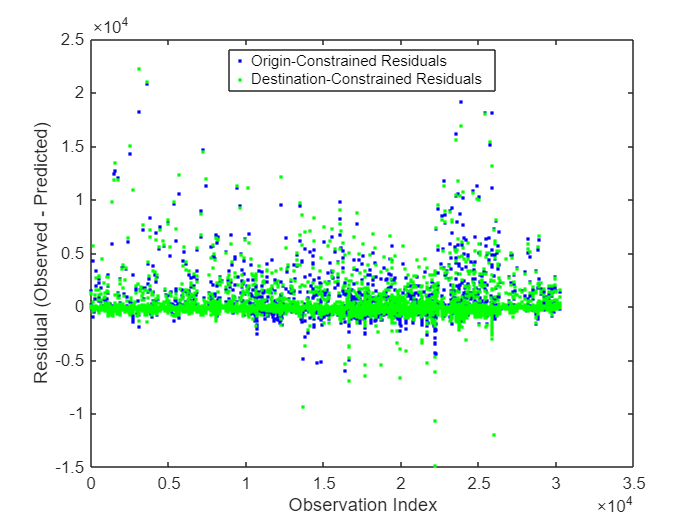

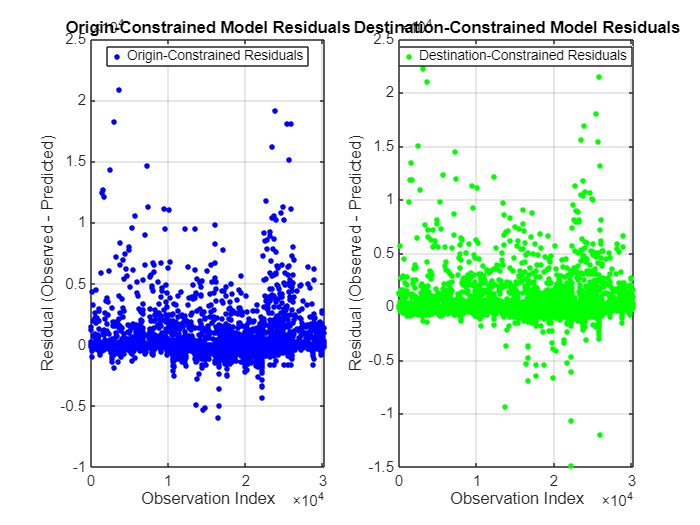

% plot log-scatter and residuals for alpha and c
plotting4(UTLAdata)

# New Centres

% Creating gravity model
originSums = UTLAdata.originSums(:); % Ensure column vector
destinationSums = UTLAdata.destinationSums(:)'; % Ensure row vector
numerator = originSums * destinationSums * c; % Outer product
denominator = UTLAdata.distanceMatrixImproved .^ alpha; % Element-wise power
UTLAdata.gravityUcentres = numerator ./ denominator; % Element-wise division

diagMask = eye(size(UTLAdata.distanceMatrixImproved)) > 0;
% Copy the distance matrix and replace diagonal elements with NaN
distanceMatrixNoDiag = UTLAdata.distanceMatrixImproved;
distanceMatrixNoDiag(diagMask) = NaN;

% Creating origin-constrained gravity model
% Step 1: Calculate the denominator sum for each origin
% denominatorSum is a column vector of sums for each origin
denominatorSum = nansum(destinationSums ./ (distanceMatrixNoDiag .^ alpha), 2);
% Step 2: Calculate the normalization factor (A_i)
% originSums is a column vector, element-wise division ensures A_i is calculated per origin
A = originSums ./ denominatorSum;
% Step 3: Create the origin-constrained gravity model
% Recreate gravity model with normalization applied
% A is a column vector, destinationSums is a row vector, so implicit broadcasting works
UTLAdata.gravityOcentres = (A .* destinationSums) ./ (UTLAdata.distanceMatrixImproved .^ alpha);

% Step 1: Calculate the denominator sum for each destination
% denominatorSum is a row vector of sums for each destination
denominatorSum = nansum(originSums ./ (distanceMatrixNoDiag .^ alpha), 1);

% Step 2: Calculate the normalization factor (B_j)
% destinationSums is a row vector, element-wise division ensures B_j is calculated per destination
B = destinationSums ./ denominatorSum;

% Step 3: Create the destination-constrained gravity model
% B is a row vector, originSums is a column vector, so implicit broadcasting works
UTLAdata.gravityDcentres = (originSums .* B) ./ (UTLAdata.distanceMatrixImproved .^ alpha);

Verifying constrained models

UTLAdata.gravityOcentres(logical(eye(size(UTLAdata.gravityOcentres)))) = 0;
UTLAdata.gravityDcentres(logical(eye(size(UTLAdata.gravityDcentres)))) = 0;
gravityOoriginsums= sum(UTLAdata.gravityOcentres,2)

gravityOoriginsums = 1.0e+05 *

    0.3713
    0.5543
    0.5435
    0.8516
    0.4897
    0.5845
    1.0282
    0.6337
    0.5908
    1.1710


gravityOdestinationsums = sum(UTLAdata.gravityOcentres)

gravityOdestinationsums = 1.0e+05 *

    0.2871    0.7745    0.2864    0.9233    0.4393    0.6889    1.4884    0.9833    0.3754    0.7238    0.9395    0.4185    0.5893    0.8151    1.4624    1.6461    0.1691    1.6883    0.5911    0.7678    1.5072    1.0113    2.8895    1.0350    1.8251    0.8075    0.4559    0.9723    0.8284    1.1803    0.7230    0.9168    1.1339    0.6474    0.8013    0.9795    0.8734    0.9103    0.9656    1.5057    0.9901    0.8505    1.4786    0.3706    1.1541    1.9072    1.4246    1.0021    0.7908    0.0011


gravityDoriginsums = sum(UTLAdata.gravityDcentres,2)

gravityDoriginsums = 1.0e+05 *

    0.3216
    0.7035
    0.3385
    0.9090
    0.4125
    0.7146
    1.3003
    0.8912
    0.3564
    0.7066


gravityDdestinationsums = sum(UTLAdata.gravityDcentres)

gravityDdestinationsums = 1.0e+05 *

    0.3311    0.6080    0.4630    0.8707    0.5132    0.5643    1.1611    0.6868    0.6137    1.1836    1.4664    0.6802    0.7801    1.0269    1.2243    1.5935    0.2028    1.5247    0.8835    0.8750    1.1657    0.9425    2.5292    0.9741    1.5054    1.2168    0.5618    1.1397    1.0663    0.8819    0.7999    0.8230    1.1610    0.5970    0.9097    0.8974    0.7288    0.7957    0.8487    1.5391    1.4287    1.0374    1.1278    0.5677    2.0282    1.9815    1.6975    1.4986    2.4864    0.0099


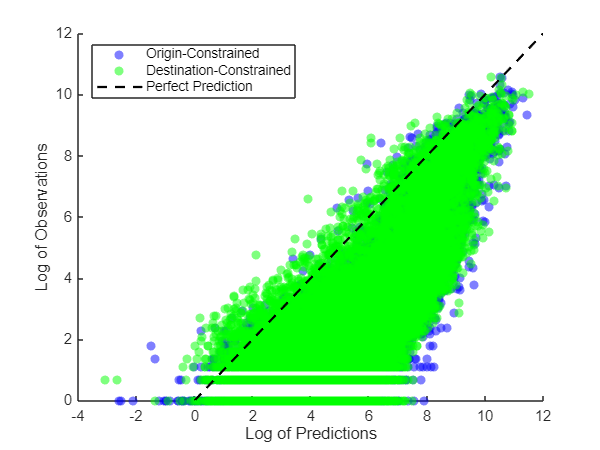

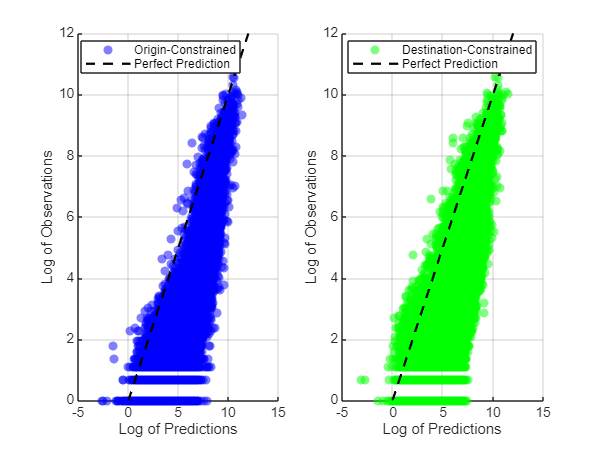

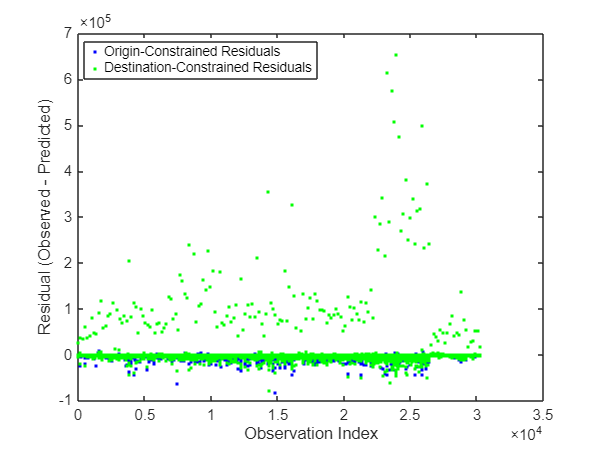

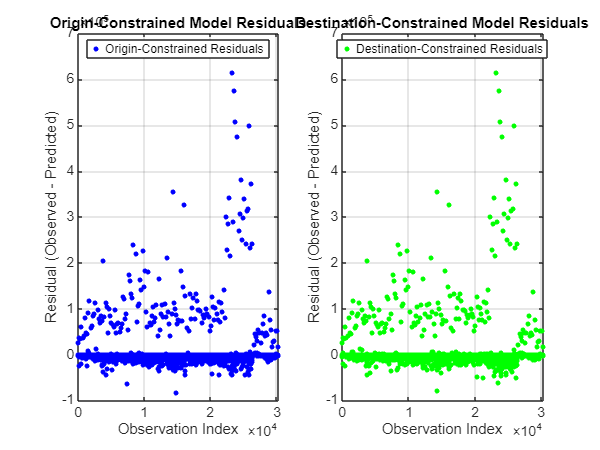

% plot log-scatter and residuals for alpha and c
plotting5(UTLAdata)


rmsecalcs(UTLAdata)

rmse o1
   2.7631e+03

rmse d1
   2.8411e+03

rmse o2
   2.3264e+03

rmse d2
   2.3860e+03



## Which locations are under/over predicted and how does this vary between the models

overunder(UTLAdata, 2800,-50000)

      653121

Journeys that are majorly underpredicted by origin model
from Staffordshire to Stoke-on-Trent
from Warwickshire to West Northamptonshire
from Bexley to Kent
from Stoke-on-Trent to Staffordshire
from Isle of Anglesey to Gwynedd
from Conwy to Denbighshire
Number of journeys that are majorly underpredicted by origin model
     6

Journeys that are majorly underpredicted by destination model
from Staffordshire to Stoke-on-Trent
from Lincolnshire to Peterborough
from Northumberland to Newcastle upon Tyne
from Essex to City of London
from Kent to Bexley
from Kent to Bromley
from Newham to Westminster
from Stoke-on-Trent to Staffordshire
from Hampshire to Surrey
from Staffordshire to Warwickshire
from Isle of Anglesey to Gwynedd
from Conwy to Denbighshire
Number of journeys that are majorly underpredicted by destination model
    12

Journeys that are majorly overpredicted by origin models
from Lancashire to Blackburn with Darwen
from Leicestershire to Leicester
from South Glouc

and now for the improved centres

overunder_newcentres(UTLAdata, 2800,-50000)

Journeys that are majorly underpredicted by origin model new centres
from Lancashire to Blackpool
from East Riding of Yorkshire to Kingston upon Hull, City of
from Kingston upon Hull, City of to East Riding of Yorkshire
from Wirral to Cheshire West and Chester
from Flintshire to Cheshire West and Chester
from North Tyneside to Northumberland
from Medway to Kent
from Bexley to Kent
from Walsall to Staffordshire
from Wolverhampton to Staffordshire
from Coventry to Warwickshire
from Isle of Anglesey to Gwynedd
from Conwy to Denbighshire
Number of journeys that are majorly underpredicted by origin model new centres
    13

Journeys that are majorly underpredicted by destination model new centres
from Redcar and Cleveland to Middlesbrough
from Lancashire to Blackpool
from East Riding of Yorkshire to Kingston upon Hull, City of
from Kingston upon Hull, City of to East Riding of Yorkshire
from Nottinghamshire to Nottingham
from Lincolnshire to Peterborough
from Essex to Thurrock
from Flintshi